%Read in the Color Image and Convert it to Grayscale
I=imread('IM_00240.TIF')

I = 512×512 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

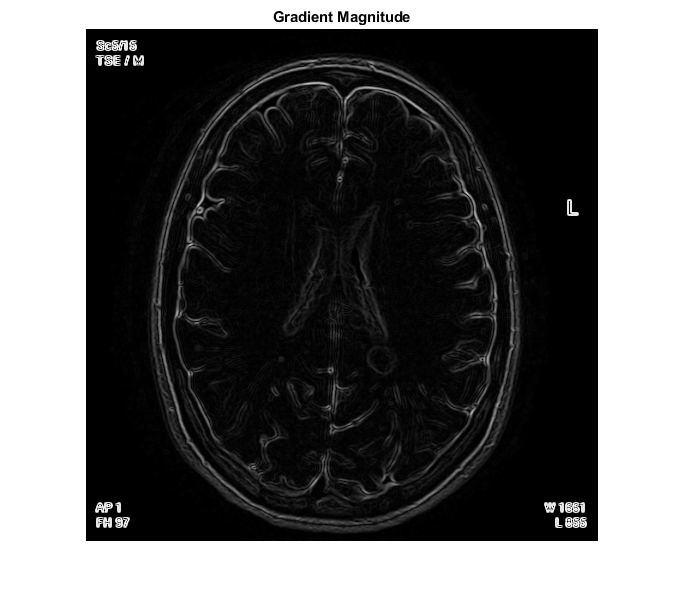


%Use the Gradient Magnitude as the Segmentation Function
gmag = imgradient(I);
imshow(gmag,[])
title('Gradient Magnitude')

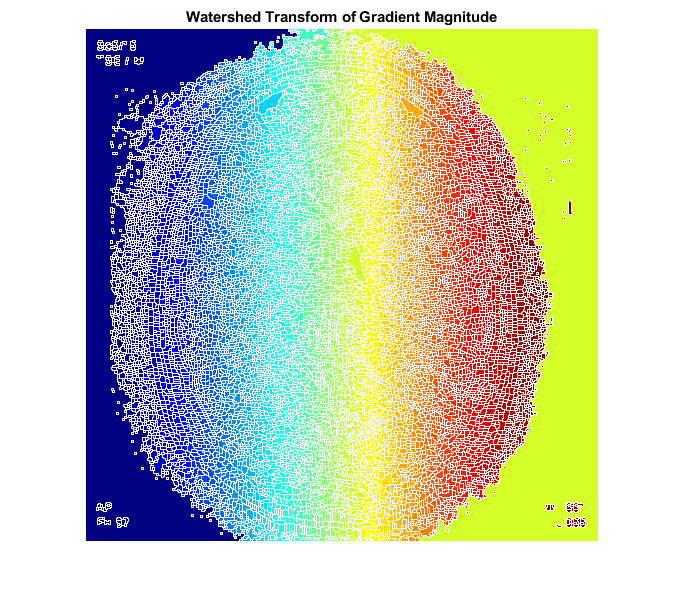

% segment the image by using the watershed transform directly on the gradient magnitude
L = watershed(gmag);
Lrgb = label2rgb(L);
imshow(Lrgb)
title('Watershed Transform of Gradient Magnitude')

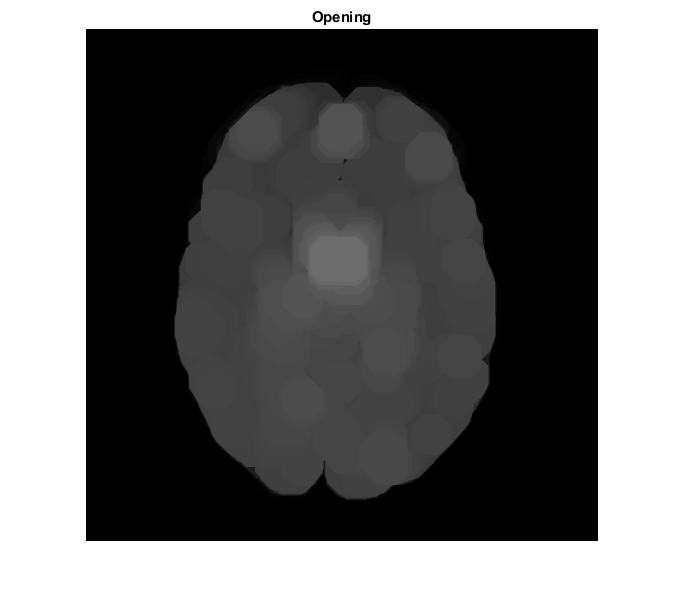


%Mark the Foreground Objects
se = strel('disk',20);
Io = imopen(I,se);
imshow(Io)
title('Opening')

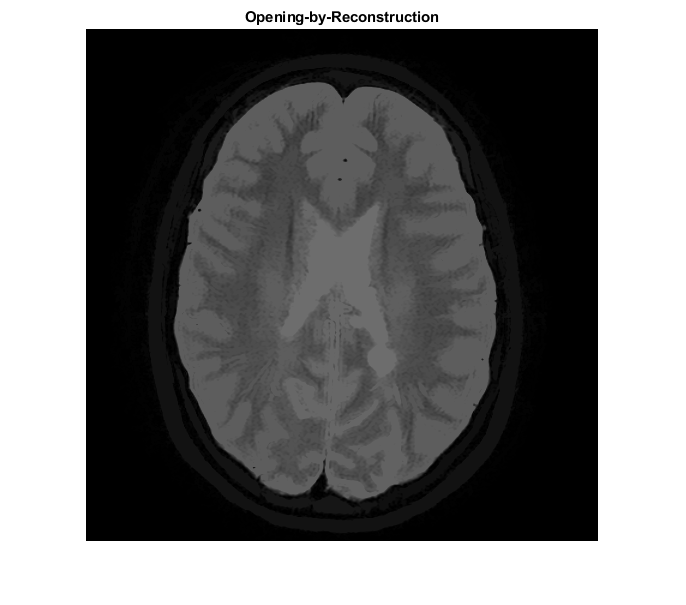


%compute the opening-by-reconstruction using imerode and imreconstruct
Ie = imerode(I,se);
Iobr = imreconstruct(Ie,I);
imshow(Iobr)
title('Opening-by-Reconstruction')

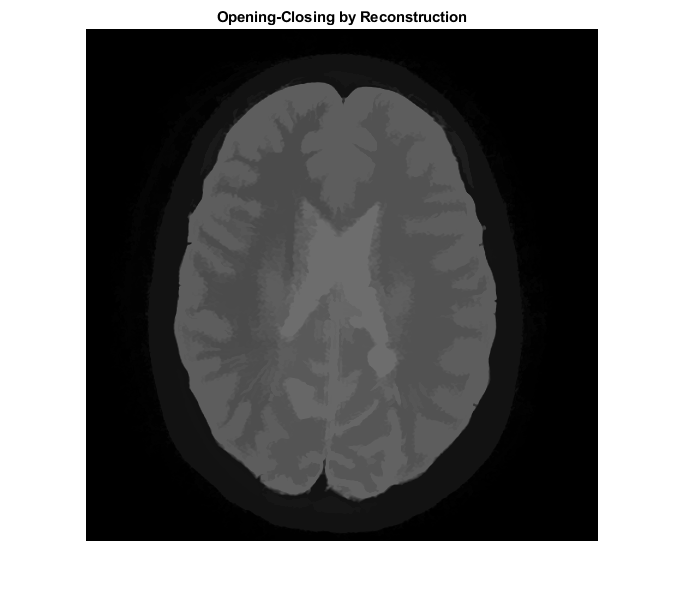


% %regular morphological closing
% Ioc = imclose(Io,se);
% imshow(Ioc)
% title('Opening-Closing')

%opening-closing by reconstruction to remove small blemishes without affecting the overall shapes of the objects
Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr)
title('Opening-Closing by Reconstruction')

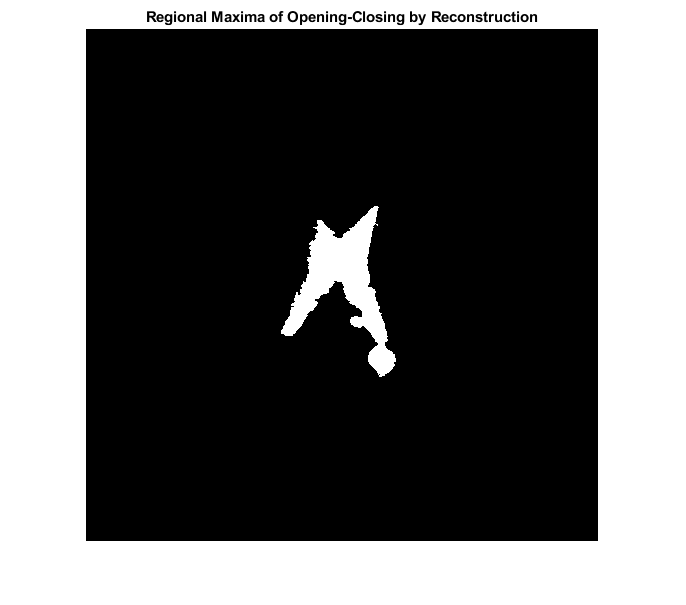


%Calculate the regional maxima of Iobrcbr to obtain good foreground markers
fgm = imregionalmax(Iobrcbr);
imshow(fgm)
title('Regional Maxima of Opening-Closing by Reconstruction')

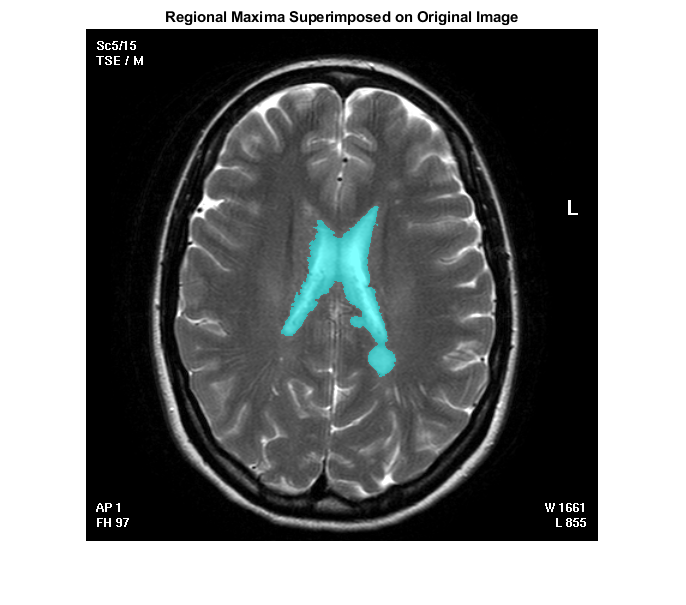


%superimpose the foreground marker image on the original image
I2 = labeloverlay(I,fgm);
imshow(I2)
title('Regional Maxima Superimposed on Original Image')

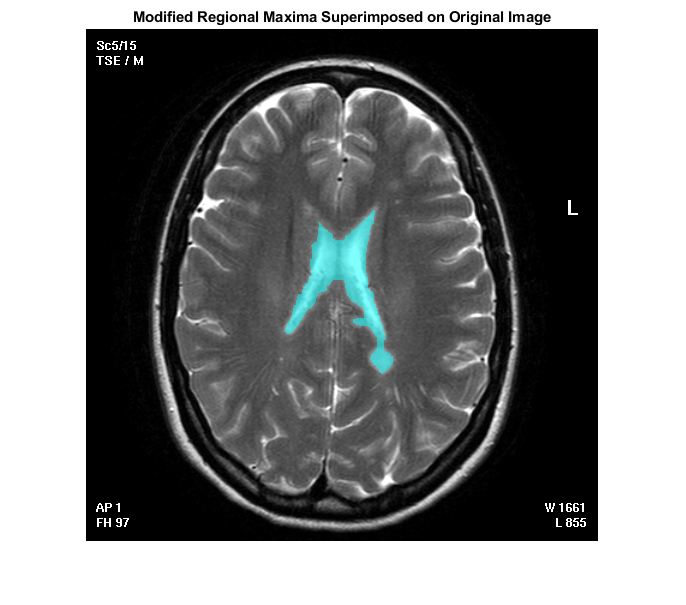

%clean the edges of the marker blobs and then shrink them a bit by a closing followed by an erosion.
se2 = strel(ones(5,5));
fgm2 = imclose(fgm,se2);
fgm3 = imerode(fgm2,se2);
%remove all blobs that have fewer than a certain number of pixels by Modified Regional Maxima Superimposed
fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(I,fgm4);
imshow(I3)
title('Modified Regional Maxima Superimposed on Original Image')

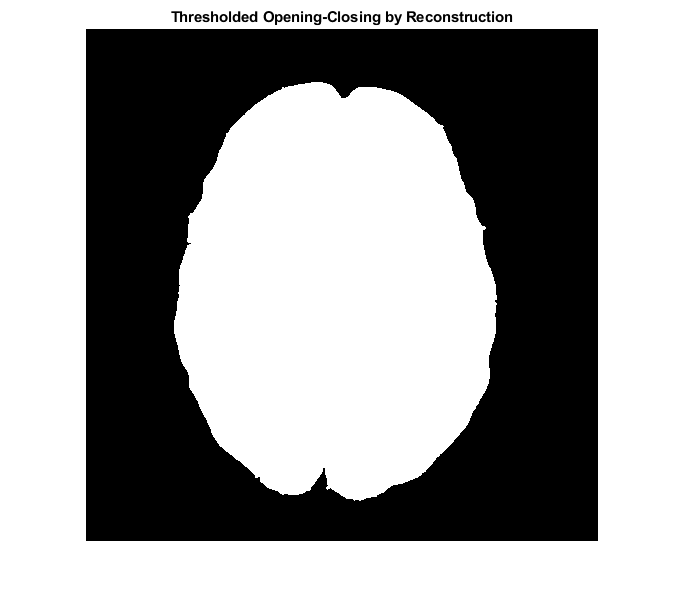


% Compute Background Markers
bw = imbinarize(Iobrcbr);
imshow(bw)
title('Thresholded Opening-Closing by Reconstruction')

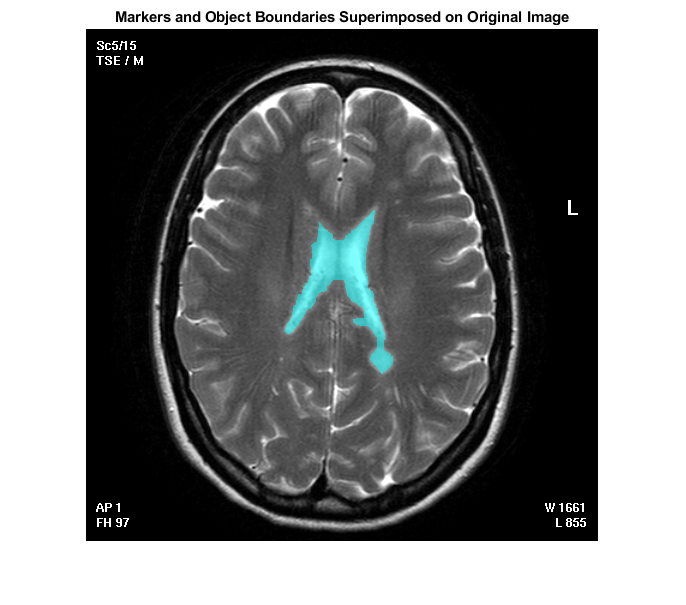


% D = bwdist(bw);
% DL = watershed(D);
% bgm = DL == 0;
% imshow(bgm)
% title('Watershed Ridge Lines)')

%Compute the Watershed Transform of the Segmentation Function.
gmag2 = imimposemin(gmag, bgm | fgm4);
L = watershed(gmag2);

%Visualize the Result
labels = imdilate(L==0,ones(3,3)) + 2*bgm + 3*fgm4;
I4 = labeloverlay(I,labels);
imshow(I4)
title('Markers and Object Boundaries Superimposed on Original Image')

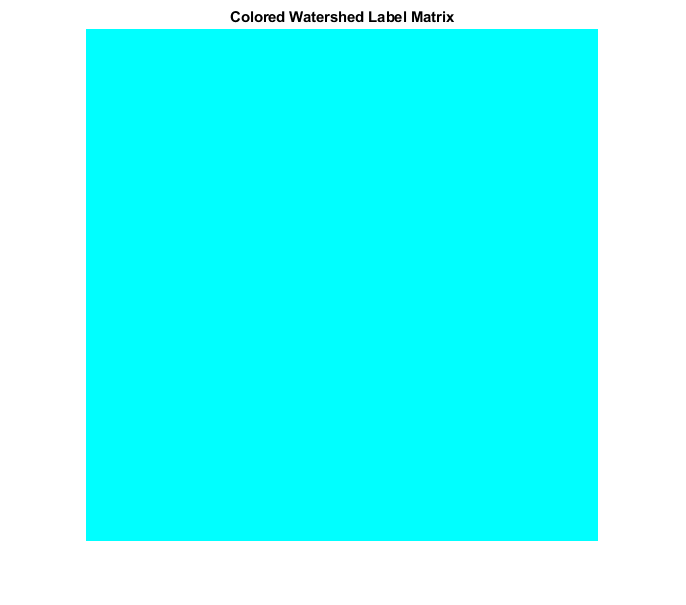

Lrgb = label2rgb(L,'jet','w','shuffle');
imshow(Lrgb)
title('Colored Watershed Label Matrix')

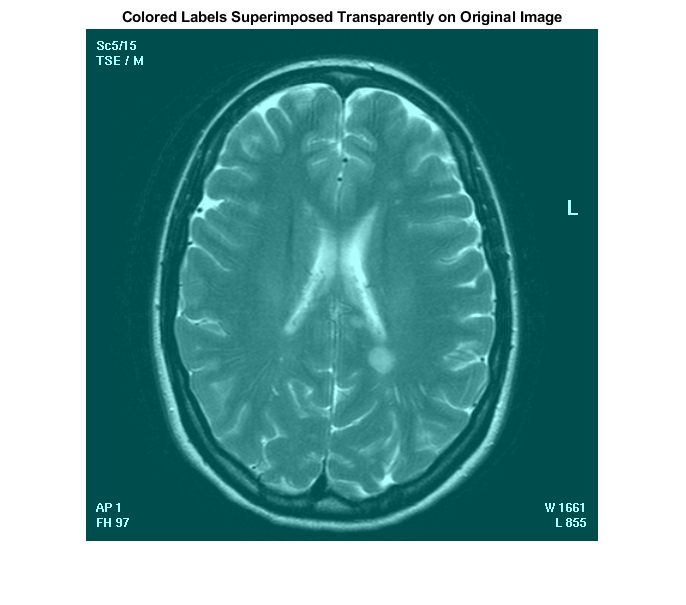

figure
imshow(I)
hold on
himage = imshow(Lrgb);
himage.AlphaData = 0.3;
title('Colored Labels Superimposed Transparently on Original Image')